# Surfaces defined explicitly by functions

If we assign the output of a function of two variables $f\left(x,y\right)$ to be a third variable, $z=f\left(x,y\right),$then the set of points in 3D define a surface. For example, $z = x^2 + y^2$ defines a paraboloid. This explicit surface can be visualized in MATLAB using a variety of techniques: we will focus here on using the **surf** function. First, we will define a domain using **meshgrid**

x = linspace(-2,2,100)

x =    -2.0000   -1.9596   -1.9192   -1.8788   -1.8384   -1.7980   -1.7576   -1.7172   -1.6768   -1.6364   -1.5960   -1.5556   -1.5152   -1.4747   -1.4343   -1.3939   -1.3535   -1.3131   -1.2727   -1.2323   -1.1919   -1.1515   -1.1111   -1.0707   -1.0303   -0.9899   -0.9495   -0.9091   -0.8687   -0.8283   -0.7879   -0.7475   -0.7071   -0.6667   -0.6263   -0.5859   -0.5455   -0.5051   -0.4646   -0.4242   -0.3838   -0.3434   -0.3030   -0.2626   -0.2222   -0.1818   -0.1414   -0.1010   -0.0606   -0.0202


y = linspace(-2,2,100)

y =    -2.0000   -1.9596   -1.9192   -1.8788   -1.8384   -1.7980   -1.7576   -1.7172   -1.6768   -1.6364   -1.5960   -1.5556   -1.5152   -1.4747   -1.4343   -1.3939   -1.3535   -1.3131   -1.2727   -1.2323   -1.1919   -1.1515   -1.1111   -1.0707   -1.0303   -0.9899   -0.9495   -0.9091   -0.8687   -0.8283   -0.7879   -0.7475   -0.7071   -0.6667   -0.6263   -0.5859   -0.5455   -0.5051   -0.4646   -0.4242   -0.3838   -0.3434   -0.3030   -0.2626   -0.2222   -0.1818   -0.1414   -0.1010   -0.0606   -0.0202


[X,Y]=meshgrid(x,y)

X =    -2.0000   -1.9596   -1.9192   -1.8788   -1.8384   -1.7980   -1.7576   -1.7172   -1.6768   -1.6364   -1.5960   -1.5556   -1.5152   -1.4747   -1.4343   -1.3939   -1.3535   -1.3131   -1.2727   -1.2323   -1.1919   -1.1515   -1.1111   -1.0707   -1.0303   -0.9899   -0.9495   -0.9091   -0.8687   -0.8283   -0.7879   -0.7475   -0.7071   -0.6667   -0.6263   -0.5859   -0.5455   -0.5051   -0.4646   -0.4242   -0.3838   -0.3434   -0.3030   -0.2626   -0.2222   -0.1818   -0.1414   -0.1010   -0.0606   -0.0202
   -2.0000   -1.9596   -1.9192   -1.8788   -1.8384   -1.7980   -1.7576   -1.7172   -1.6768   -1.6364   -1.5960   -1.5556   -1.5152   -1.4747   -1.4343   -1.3939   -1.3535   -1.3131   -1.2727   -1.2323   -1.1919   -1.1515   -1.1111   -1.0707   -1.0303   -0.9899   -0.9495   -0.9091   -0.8687   -0.8283   -0.7879   -0.7475   -0.7071   -0.6667   -0.6263   -0.5859   -0.5455   -0.5051   -0.4646   -0.4242   -0.3838   -0.3434   -0.3030   -0.2626   -0.2222   -0.1818   -0.1414   -0.1010   -0.0606   -0

Y =    -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000
   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1.9596   -1

We now define a function that computes the z-coordinates corresponding to the paraboloid. You will find this function at the end of this script, and we copy it here for clarity

**function res = paraboloid(x,y)**

**    res = x.^2 + y.^2**

**end**

Notice that we use the **.^** operator since the input arguments to this function can and will be matrices. Now we can call this function and visualize the surface

Z = paraboloid(X,Y)

Z =     8.0000    7.8400    7.6833    7.5298    7.3797    7.2327    7.0891    6.9487    6.8115    6.6777    6.5471    6.4198    6.2957    6.1749    6.0573    5.9431    5.8321    5.7243    5.6198    5.5186    5.4207    5.3260    5.2346    5.1464    5.0615    4.9799    4.9015    4.8264    4.7546    4.6861    4.6208    4.5587    4.4999    4.4444    4.3922    4.3432    4.2975    4.2551    4.2159    4.1800    4.1473    4.1179    4.0918    4.0690    4.0494    4.0331    4.0200    4.0102    4.0037    4.0004
    7.8400    7.6800    7.5233    7.3699    7.2197    7.0727    6.9291    6.7887    6.6516    6.5177    6.3871    6.2598    6.1357    6.0149    5.8974    5.7831    5.6721    5.5643    5.4599    5.3586    5.2607    5.1660    5.0746    4.9864    4.9015    4.8199    4.7416    4.6665    4.5946    4.5261    4.4608    4.3987    4.3400    4.2845    4.2322    4.1832    4.1375    4.0951    4.0559    4.0200    3.9873    3.9580    3.9318    3.9090    3.8894    3.8731    3.8600    3.8502    3.8437    3

surf(X,Y,Z)

**Exercise 1: **Use the **shading** function in Matlab to visualize this surface in three different ways (flat, faceted, interp)

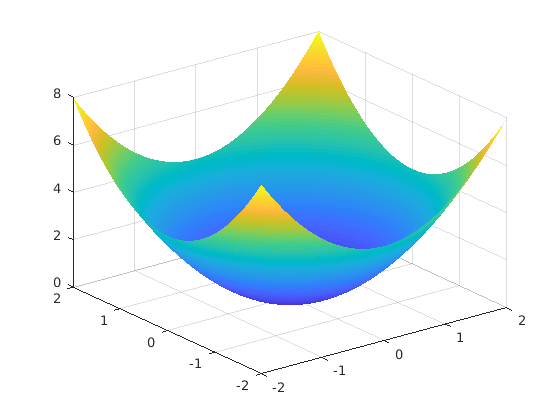

shading('interp')

## Contour plots

It is often helpful to visualize a surface by drawing the contours defined by holding z constant. For example, if we define z=1 in the equation for the paraboloid we obtain $x^2 + y^2 = 1$, which we know to be the equation of a circle of radius 1, centered at the origin. Choosing different values of z will define circles of radius $\sqrt{z}$.

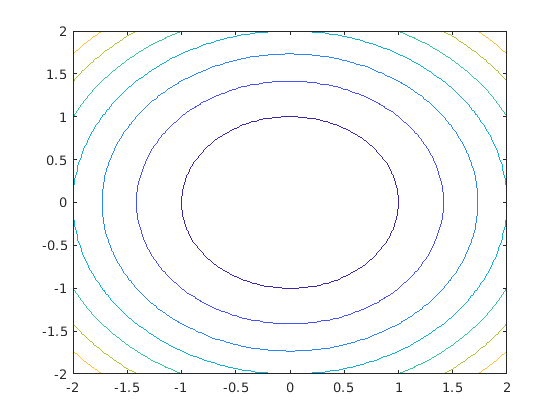

contour(X,Y,Z)

By default, **contour** will draw a set of contours that are chosen automatically by MATLAB. We can, of course, control the contours that are displayed by specifying them. The following example draws three contours corresponding to values of 1, 2, and 3.

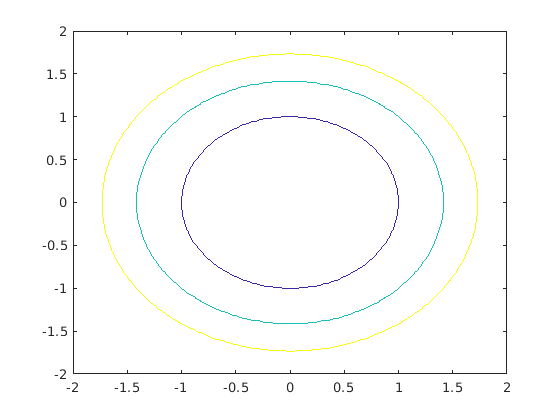

contour(X,Y,Z,[1,2,3])

 The results are circles of radius 1, $\sqrt{2}$, and $\sqrt{3}$ as you might have expected.

**Exercise 2: **Use the documentation for **contour** to figure out how to label each contour with the height.

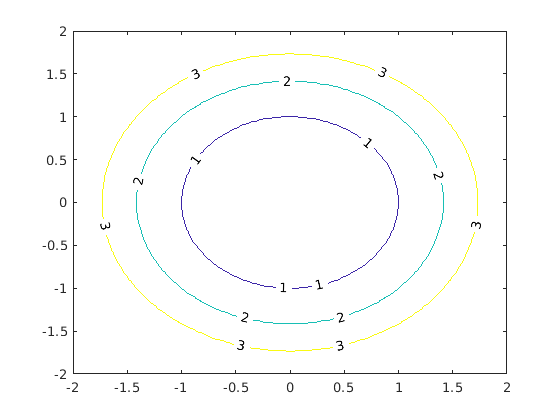

contour(X,Y,Z,[1,2,3],'ShowText','on')

**Exercise 3:** Consider the surface defined by $z = c \left( \frac{x^2}{a^2} + \frac{y^2}{b^2} \right)$. 

- Write a function that accepts x, y, a, b,and c as input, and returns the value of z as output. 

- Visualize the surface (using **surf** and **contour**) for different values of a, b, and c. 

- What features of the surface do a, b, and c control?

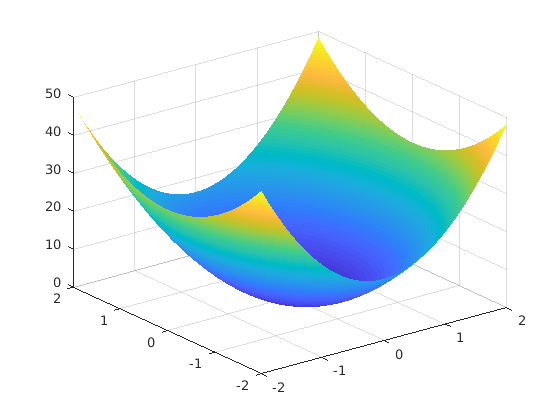

a = 0.5;
b = 0.7;
c = 2.0;
Z = myfunc1(X,Y,a,b,c);
surf(X,Y,Z)
shading('interp')

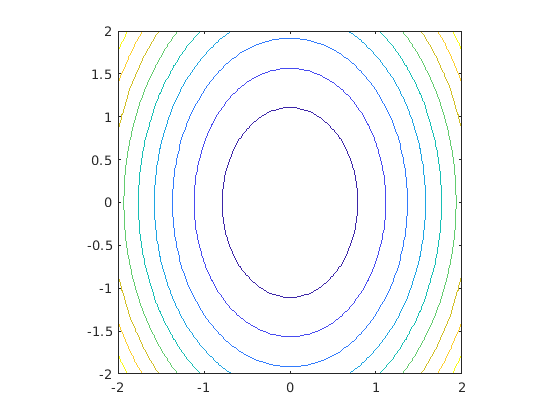

contour(X,Y,Z)
axis('equal')

## Function definitions

function res = paraboloid(x,y)
    res = x.^2 + y.^2;
end

function res = myfunc1(x,y,a,b,c)
    res = c*(x.^2/a^2 + y.^2/b^2);
end